# Chapter 5 - Frequency Response Anaysis 

## Section 2 : Plotting Nyquist Diagrams with Matlab

clear all
clc


**Notes on Nyquist plots: **

Nyquist plots are typically used in the frequency-response respresentation of linear time-invariant feedback control systems. They are polar plots (Bode = rectangular). Nyquist plots magnitude vs the phase angle on polar coordinates as w is varied from 0 to inf, resulting in a locus of vectors as w is varied from 0 to inf. 

        Positive phase angle = CCW 

        Negative phase angle = CW 

Nyquist Stability Criterion: Open Loop TF (G(s)H(s)) 

-  Z = N + P 

                  Z = # zeros of characteristic equation [ 1 + G(s)H(s) ] in RHP

                  N = # CW encirclements of the [ -1 + j0 ] point (-1 on REAL axis) 

                  P = # poles of G(s)H(s) in the RHP

                              * If P > 0, Then N = -P and Z = 0 to be stable

                              ** If P = 0, Then N = Z (no encirclements) to be stable

        2.   Multi-loop systems may include poles in the RHP ==> (even though an inner loop may be        

              unstable, the entire closed-loop system can be made stable by proper design). Number of 

              encirclements, N, is not sufficient to detect instability. Instead, apply Routh Criterion to the

              characteristic equation [ 1 + G(s)H(s) ] to determine stability. 

        3. If the locus of G(s)H(s) passes through [ -1 + j0 ] point, then zeros of the characteristic 

            equation, are located on the jw-axis. This is not desirable for practical control systems. 

More on stablility -- System is stable if: 

      1. There are no encirclements of [ -1 + j0 ] and no poles of

          G(s)H(s) in the RHP. 

      2. There are 1 or more CCW encirclements of [ -1 + j0 ] and the #

          of CCW (N) is equal to the # of poles of G(s)H(s) in the RHP. 

          -N = P

      3. There are 1 or  more CW encirclements of [ -1 + j0 ]...this

          system is UNSTABLE

## 5-7 Draw a Nyquist plot

Open loop TF: G(s) = 1/ (s^2 + 0.8s + 1)

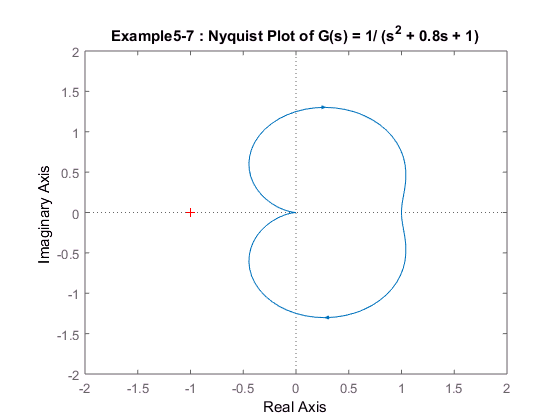

num = [1];
den = [1 0.8 1];

% Manually set ranges
v = [-2 2 -2 2];

figure
nyquist(num, den), axis(v)
title('Example5-7 : Nyquist Plot of G(s) = 1/ (s^2 + 0.8s + 1)')

## 5-8 See what happens if a TF divides by zero

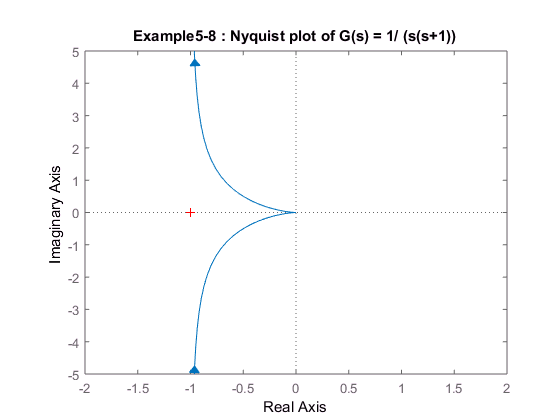

num2 = [1];
den2 = [1 1 0];
v2 = [-2 2 -5 5];

figure 
nyquist(num2, den2), axis(v2)
title('Example5-8 : Nyquist plot of G(s) = 1/ (s(s+1))')

## 5-9 Nyquist plot with State Space

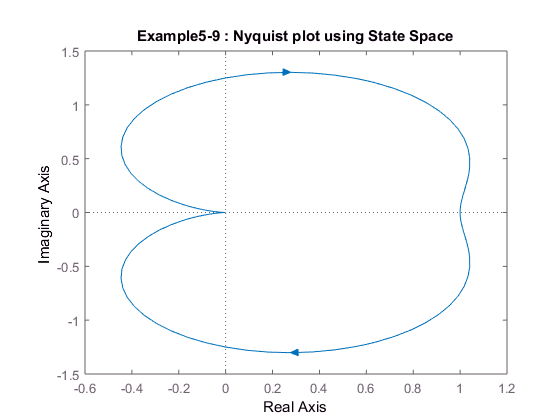

clear
clc

%This system has as single input, u, and a single output, y. 
%Define system 
A = [0 1; -25 -4];
B = [0; 25];
C = [1 0];
D = 0;

figure;
nyquist(A,B,C,D)
v = [-0.6 1.2 -1.5 1.5]; axis(v)
title('Example5-9 : Nyquist plot using State Space')

## 5-10 Two input/two output Nyquist plot with State Space

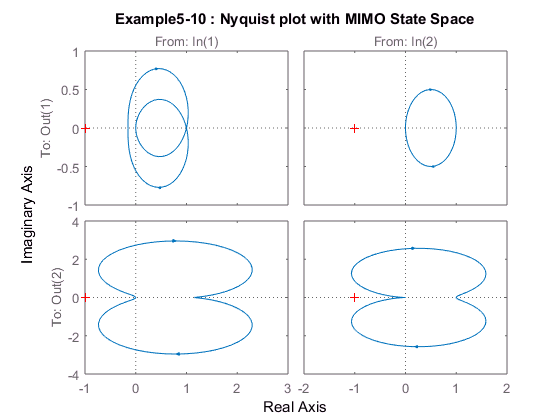

%This system involves two inputs (U1 & U2) and two outputs (Y1 & Y2).
%Define system 
A = [-1 -1; 6.5 0];
B = [1 1; 1 0];
C = [1 0; 0 1];
D = [0 0; 0 0];

figure
nyquist(A,B,C,D)
title('Example5-10 : Nyquist plot with MIMO State Space')

 Determined stability of system. It does not encircle -1, but are there poles in the RHP...

## 5-11 Unity-feedback system Nyquist plot

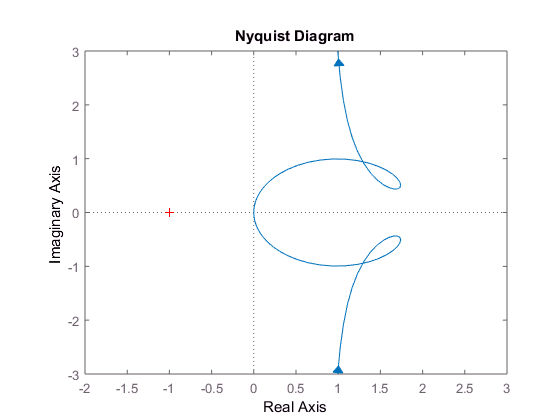

% Open loop TF 
Gs = tf([20 20 10], [1 11 10 0]);

%plot 
figure
nyquist(Gs) 
v = [-2 3 -3 3]; axis(v) 

This system is stable bc there are no encirclements around -1 (N = 0), and there are no Open loop poles in the RHP (P = 0). Therefore, according to Z = N + P = 0. The closed-loop system is stable.

## 5-12 Draw Example 5-11 for only positive frequency region.

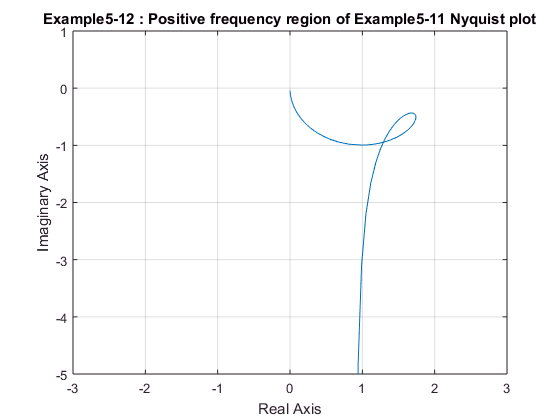

%Define positive frequency range, using different increments
w1 = 0.1 : 0.1 : 10;
w2 = 10 : 2 : 100;
w3 = 100 : 10 : 500;
w = [w1 w2 w3];

%Determine nyquist locus
num = [20 20 10];
den = [1 11 10 0];
[real, imag, w] = nyquist(num, den, w);

%plot
figure
plot(real, imag), grid
v = [-3 3 -5 1]; axis(v)
title('Example5-12 : Positive frequency region of Example5-11 Nyquist plot')
xlabel('Real Axis')
ylabel('Imaginary Axis')

Everything after "0" is negative frequency....going from 0 to -inf

## 5-13 Using Example 5-12, change frequency range

Locate specific frequencies, w, and find magnitudes and phase angles at the specific points. 

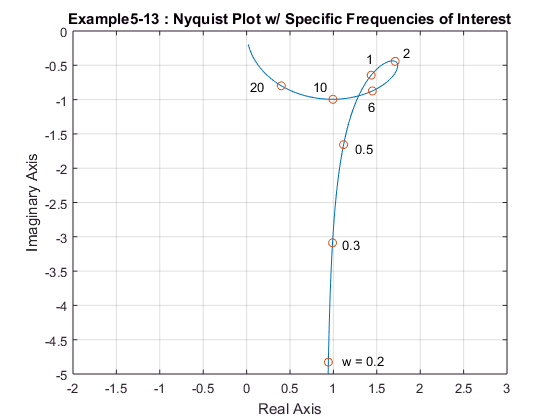

%Define frequency vector
ww = logspace(-1, 2, 100);

%Nyquist plot
[re, im, ww] = nyquist(num, den, ww);
figure; plot(re, im), grid
v = [-2 3 -5 0]; axis(v)
title('Example5-13 : Nyquist Plot w/ Specific Frequencies of Interest')
xlabel('Real Axis')
ylabel('Imaginary Axis')
hold on

%Add labels to each frequency of interest
w = [0.2 0.3 0.5 1 2 6 10 20];
[re, im, w] = nyquist(num, den, w);
plot(re, im, 'o')
text(1.1, -4.8, 'w = 0.2')
text(1.1, -3.1, '0.3')
text(1.25, -1.7, '0.5')
text(1.37, -0.4, '1')
text(1.8, -0.3, '2')
text(1.4, -1.1, '6')
text(0.77, -0.8, '10')
text(0.037, -0.8, '20')

 To get the values of mag and phase of G(jw) a the specified w values, enter the command 

[mag, phase, w] = bode(num, den, w)


[mag, phase, w] = bode(num, den, w);


The following table shows the specified frequency values, w, and the corresponding values of magnitude and phase 


mag_and_phase = [w mag phase]

mag_and_phase =     0.2000    4.9176  -78.9571
    0.3000    3.2426  -72.2244
    0.5000    1.9975  -55.9925
    1.0000    1.5733  -24.1455
    2.0000    1.7678  -14.4898
    6.0000    1.6918  -31.0946
   10.0000    1.4072  -45.0285
   20.0000    0.8933  -63.4385


## 5-14 Unity, positive feedback system with the following OL TF

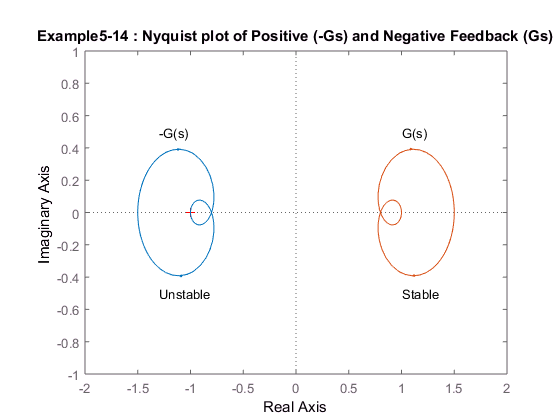

clear
clc

% Open loop TF
num2 = [-1 -4 -6];
num1 = [1 4 6];
den = [1 5 4];
Gs = tf(num1, den);

%Nyquist Plot Positive Feedback
figure 
nyquist(num2, den), grid
title('Example5-14 : Nyquist plot of Positive (-Gs) and Negative Feedback (Gs)')
hold on 
nyquist(num1, den), grid
v = [-2 2 -1 1]; axis(v);
text(1, 0.5, 'G(s)')
text(1, -0.5, 'Stable')
text(-1.3, 0.5, '-G(s)')
text(-1.3, -0.5, 'Unstable')


% Positive Feedback [ Gs / 1 - Gs ]
positive_fb = feedback(Gs, 1, +1)


positive_fb =
 
  s^2 + 4 s + 6
  -------------
      s - 2
 
Continuous-time transfer function.



negative_fb = feedback(Gs, 1, -1)


negative_fb =
 
   s^2 + 4 s + 6
  ----------------
  2 s^2 + 9 s + 10
 
Continuous-time transfer function.



## 5-15 Open Loop TF with different values of K.

Determine the stability region of K. 

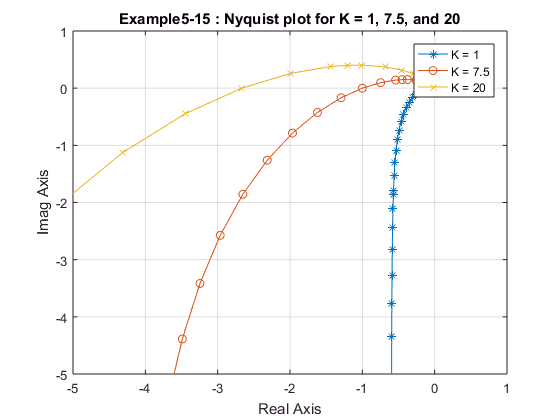

clear 
clc

K = [1; 7.5; 20];

% Open Loop TF
for n = 1:3;
    num = [K(n)*10];
    den = [0.1 1.5 5 0];
    
    [re(:,n), im(:,n)] = nyquist(num, den);
end

figure
plot(re(:,1), im(:,1),'-*', re(:,2), im(:,2),'-o', re(:,3), im(:,3),'-x'),grid
title('Example5-15 : Nyquist plot for K = 1, 7.5, and 20')
v = [-5 1 -5 1]; axis(v)
xlabel('Real Axis')
ylabel('Imag Axis')
legend('K = 1', 'K = 7.5', 'K = 20')

When K = 7.5, the system is critically stable bc the nyquist locus passes directly thru -1. When K > 7.5, the system is unstable.